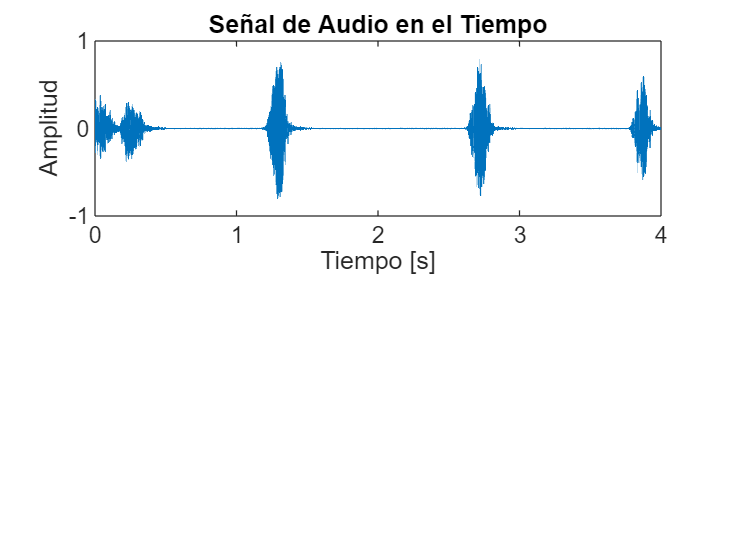

[x, Fs] = audioread('perros3.wav');
N = length(x);  % Número de muestras
t = (0:N-1)/Fs;  % Vector de tiempo para graficar la señal en segundos

% Figura para la señal en el tiempo
figure;
subplot(2,1,1); 
plot(t, x);
title('Señal de Audio en el Tiempo');
xlabel('Tiempo [s]');
ylabel('Amplitud');

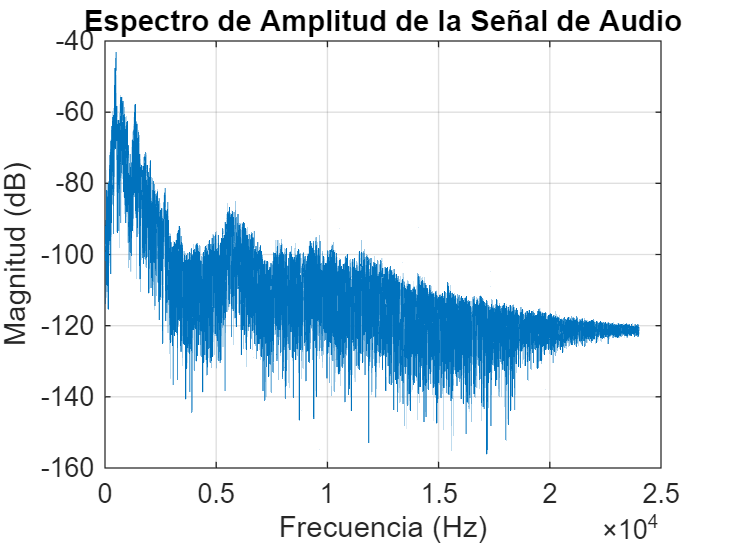


% Transformada de Fourier para visualizar el espectro de frecuencias
Y = fft(x);
f = (0:N-1)*(Fs/N);  % Vector de frecuencias
P2 = abs(Y/N);       % Espectro de amplitud bidireccional
P1 = P2(1:floor(N/2)+1); % Espectro de amplitud de un solo lado

% Graficar el espectro
figure;
plot(f(1:floor(N/2)+1), 20*log10(P1));
title('Espectro de Amplitud de la Señal de Audio');
xlabel('Frecuencia (Hz)');
ylabel('Magnitud (dB)');
grid;

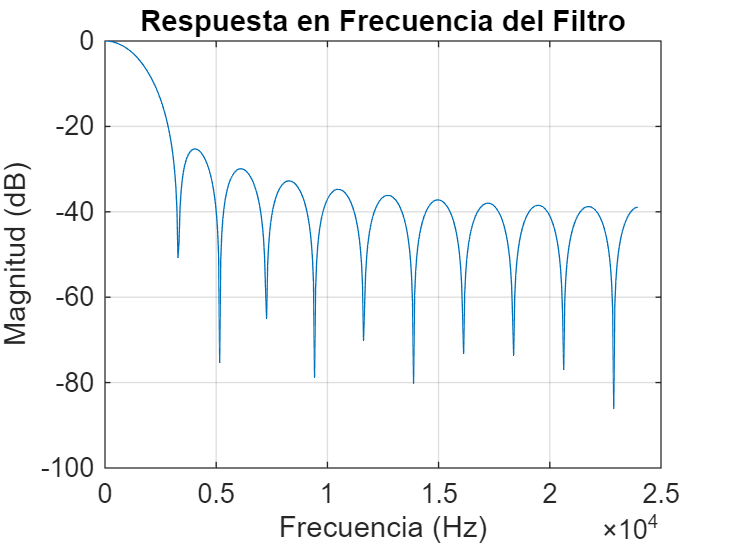


% Frecuencia de corte (ajustarla en función del análisis del espectro)
fc = 150;  % Ajusta este valor en función del espectro
Wn = (2/Fs)*fc;  % Normalización de frecuencia de corte

% Ajuste de beta en función del ancho de transición deseado
% Valores típicos de beta para la ventana de Kaiser:
% - Beta = 0: Ventana rectangular
% - Beta = 5: Ventana similar a una de Hamming
% - Beta = 8.6: Ventana similar a una de Blackman
beta = 3;  % Ajusta beta en función del ancho de transición deseado

% Diseño del filtro FIR con la ventana de Kaiser
b = fir1(20, Wn, 'low', kaiser(21, beta));

% Respuesta en frecuencia del filtro
[h, f] = freqz(b, 1, [], Fs);
figure;
plot(f, mag2db(abs(h)))
xlabel('Frecuencia (Hz)')
ylabel('Magnitud (dB)')
title('Respuesta en Frecuencia del Filtro')
grid

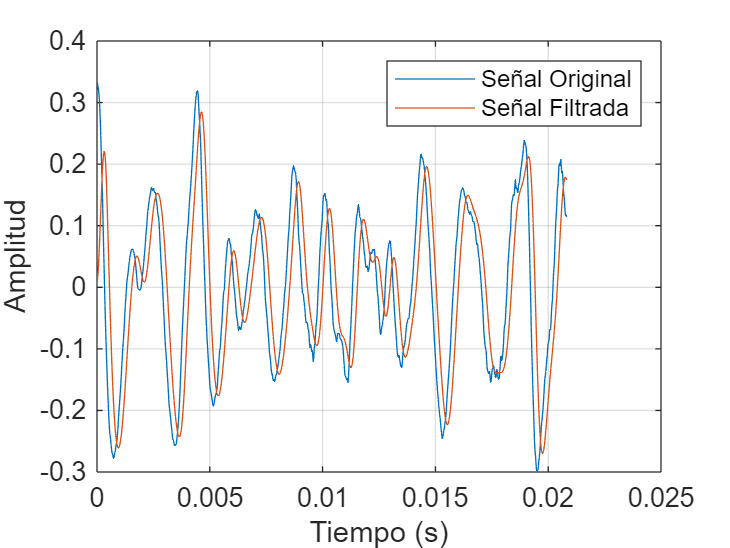


% Filtrar la señal
y = filter(b, 1, x);

% Graficar señal original y filtrada
figure;
plot(t(1:1000), x(1:1000), t(1:1000), y(1:1000))
xlabel('Tiempo (s)')
ylabel('Amplitud')
legend('Señal Original', 'Señal Filtrada')
grid

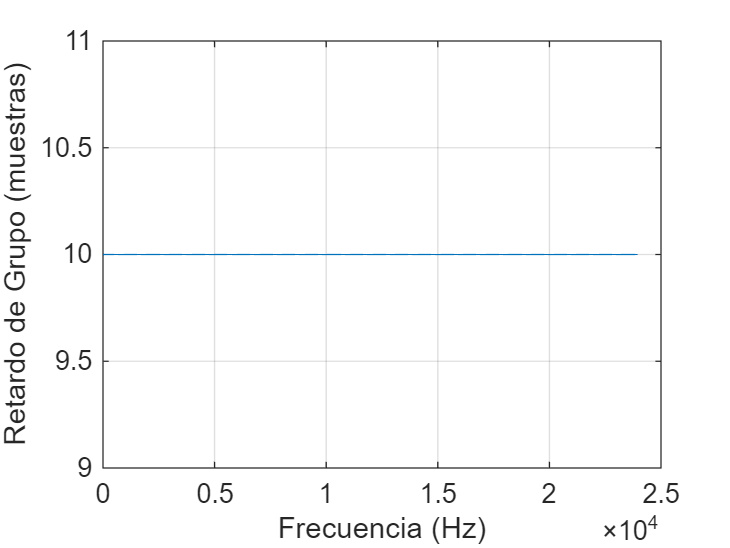


% Calcular y graficar el retardo de grupo
[gd, f] = grpdelay(b, 1, [], Fs);
figure;
plot(f, gd)
xlabel('Frecuencia (Hz)')
ylabel('Retardo de Grupo (muestras)')
grid

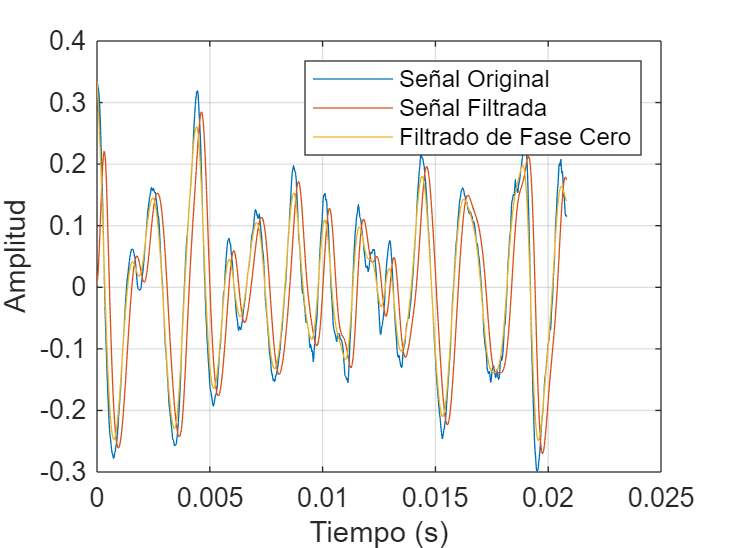


% Filtrado con fase cero
yzp = filtfilt(b, 1, x);
figure;
plot(t(1:1000), x(1:1000), t(1:1000), y(1:1000), t(1:1000), yzp(1:1000))
xlabel('Tiempo (s)')
ylabel('Amplitud')
legend('Señal Original', 'Señal Filtrada', 'Filtrado de Fase Cero', 'Location', 'NorthEast')
grid